# Running DICE

## GAMS results

Load GAMS results for further comparison:

clear

The DICE IAM model is essentially controlled by three variables: $\mu$, $S$, and $\alpha$. Every other variable can be derived or calculated as a function of those three. Hence, there are two ways of solving DICE: solving for these three control variables, or providing one or more of them as a control value. 

As a benchmark, we load the results from previous DICE runs:

% Compare results
tb = readtable('DICE2023-Excel-b-4-3-10-v18.3.xlsx', 'Range', 'A13:CD67', 'Sheet', 'GAMS', 'ReadVariableNames', true, 'ReadRowNames', true, 'VariableNamingRule','preserve');
tb.Properties.VariableNames = "Period" +string(1:81);

## Optimality Parameters

Before we start solving the problem, we need to define some optimal parameters. These determine how accurate is the solution and how long is going to take to solve the problem.

StepTolerance = 1e-7; % 1e-9 for an accurate (slower solution)
OptimalTolerance = 1e-5; % 1e-6 for an accurate (slower solution)
ConstraintTolerance = 1e-7;

%starting a thread-pool to compute gradients in parallel
if isempty(gcp('nocreate'))
    parpool threads
end
opts = optimoptions('fmincon',  ...
    'Display', 'off', ...
    "MaxIterations", 999000, ...
    "MaxFunctionEvaluations",999000, ...
    "OptimalityTolerance", OptimalTolerance, ...
    "ConstraintTolerance", ConstraintTolerance, ...
    "StepTolerance", StepTolerance, ...
    "UseParallel", true);

## Solving the full problem

% number of time steps (horizon). Each time step is 5 years
np = 81;

titer = tic;

% Load the parameters and create the objective function
params = LoadParams(np);
objFunc = @(x) -diceFunc(x, params);

% Create upper and lower bounds
alphaLB = 0.1*ones(np,1); alphaLB(1) = params.a0;
alphaUB = 100*ones(np,1); alphaUB(1) = params.a0;

lb = [zeros(np,1);  params.sLBounds; 0.1*ones(np,1)];
ub = [params.miuup; params.sUBounds; 100*ones(np,1)];

% Set the nonlinear constraints (IRFt equation)
nonlcon = @(x) IRFtcon(x, params);

% Define initial value
x0 = params.miuup(1:np)-eps;
x0 = [x0; 0.25*ones(np, 1)];
x0 = [x0; 0.4*ones(np, 1)];

% Set alpha0
Aeq = zeros(1, 3*np);
Aeq(2*np+1) = 1;
beq = params.a0;

% Sol ethe problem
[sol,fval,exitflag,output] = fmincon(objFunc, x0, [], [], Aeq, beq, lb, ub, nonlcon, opts);

tIteration = toc(titer);

sprintf('Year %d, Iterations = %d, exitFlag = %d, spent = %d secs', ...
    2020 + np*params.tstep, output.iterations,double(exitflag),round(tIteration))

ans = 'Year 2425, Iterations = 155, exitFlag = 2, spent = 19 secs'

% recover all variables
allVars = recoverAllVars(sol, params);

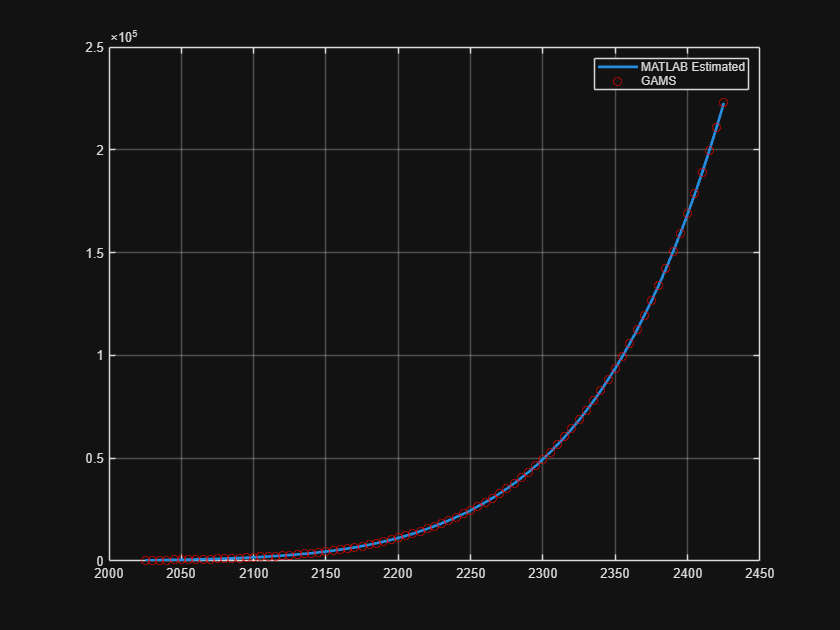

vNames = string(allVars.Properties.VariableNames(2:end));
varName = vNames(15);
figure
plot(allVars.Year, allVars.(varName), 'LineWidth', 2)
grid on; hold on;
plot(allVars.Year, tb{varName, :},'ro')
legend(["MATLAB Estimated", "GAMS"])